# Mathematical Operations On Arrays

In this document we will focus on mathematical and statistical operations on arrays. 

## Array Operations

There are many operators that behave in element-wise manner, i.e., the operation is performed on each element of the array individually.

### Mathematical Functions

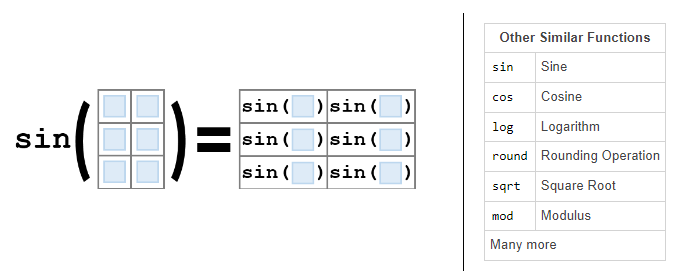

#### 
$$y(t)=A\sin(2\pi f t+\theta)$$


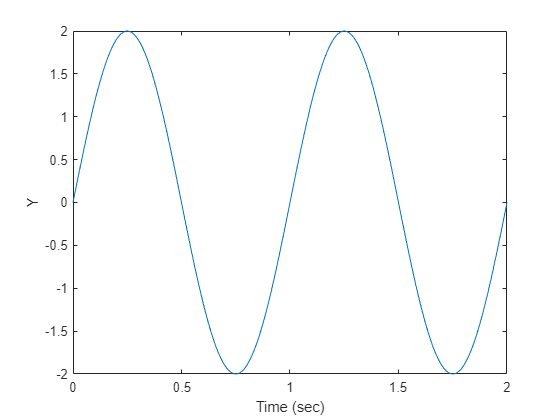

f = 1; % Hz
duration = 2; % seconds
dt = 1/100; % 100Hz
shiftAngle = 0; % rad
amplitude = 2;

t = 0:dt:duration;
y = amplitude .* sin( 2*pi*f .* t + shiftAngle );

plot(t,y);
ylabel("Y");
xlabel("Time (sec)");

### Matrix Scalar Expansion

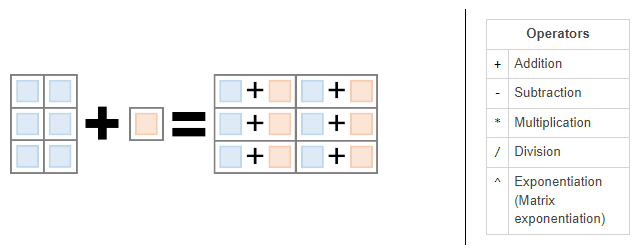

ft = 2 * pi * f * t;
plot(t,amplitude * sin( ft + shiftAngle ));
ylabel("Y");
xlabel("Time (sec)");

### Element-wise Operations

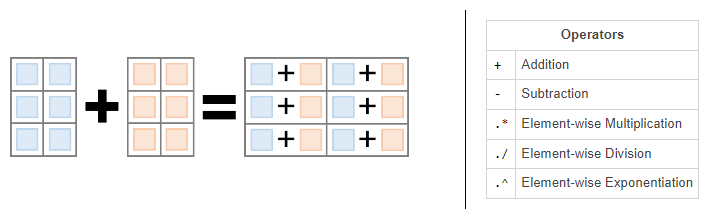

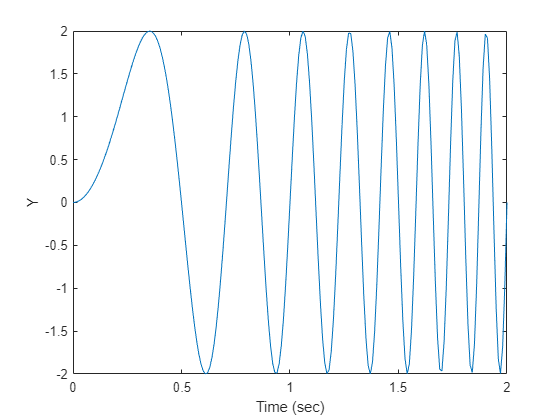

ysquared = amplitude * sin( 2 * pi * f * t.^2 + shiftAngle );
zsquared = amplitude * cos( 2 * pi * f * t.^2 + shiftAngle );
plot(t,ysquared.*zsquared);
ylabel("Y");
xlabel("Time (sec)");

### Implicit Expansion

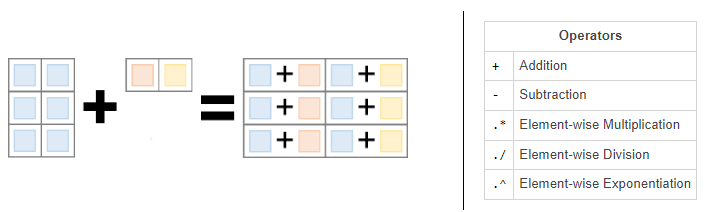

sequence = reshape(1:20,10,2)

sequence =      1    11
     2    12
     3    13
     4    14
     5    15
     6    16
     7    17
     8    18
     9    19
    10    20


dualSequence = sequence ./ [1,10]

dualSequence =    1.000000000000000   1.100000000000000
   2.000000000000000   1.200000000000000
   3.000000000000000   1.300000000000000
   4.000000000000000   1.400000000000000
   5.000000000000000   1.500000000000000
   6.000000000000000   1.600000000000000
   7.000000000000000   1.700000000000000
   8.000000000000000   1.800000000000000
   9.000000000000000   1.900000000000000
  10.000000000000000   2.000000000000000


## **Calculating Statistics Of Vectors**

### **Common Statistical Functions**

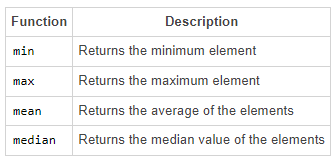

### **Using **`min`** and **`max`

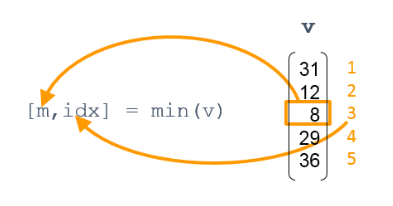

### **Ignoring NaNs**

When using statistical functions, you can ignore NaN values

### Statistical Operations on Matrices

Some common mathematical functions which calculate a value for each column in a matrix include:

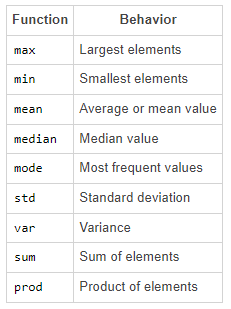

Many statistical functions accept an optional dimensional argument that specifies whether the operation should be applied to columns independently (the default) or to rows.

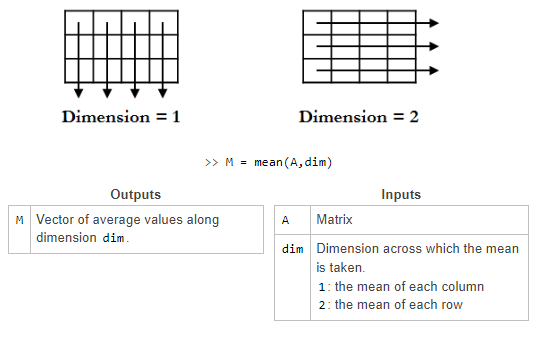

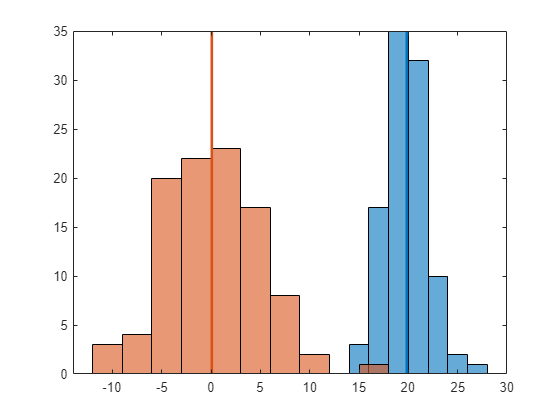

A = randn(100,2);
A(:,1) = A(:,1) * 2 + 20; % sd==2, mean==20
A(:,2) = A(:,2) * 5; % sd==5, mean==0
% calculate the mean of each column
meanA = mean(A,1);

%% Plot
fig = figure;
ax = axes(fig);
h1 = histogram(ax,A(:,1)); % blue
hold('on');
h2 = histogram(ax,A(:,2)); % orange
line(ax,meanA([1,1]),ax.YLim, 'linewidth',2,'color',ax.ColorOrder(1,:));
line(ax,meanA([2,2]),ax.YLim, 'linewidth',2,'color',ax.ColorOrder(2,:));

### Matrix Multiplication

Matrix multiplication requires that the inner dimensions agree. The resultant matrix has the outer dimensions.

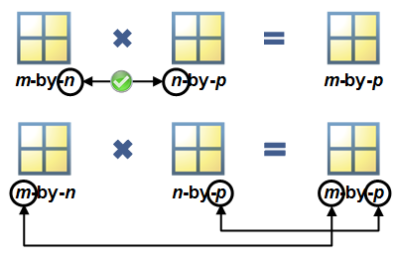

### Solving Systems of Linear Equations